# Graficación simbólica

La caja de herramientas simbólica incluye un grupo de funciones que le permiten graficar funciones simbólicas. Actualmente existen dos cajas de herramientas, una son las funciones `ez` y otra son las funciones `f`.

MATLAB recomienda las funciones `f` antes que las funciones `ez`, sin embargo, algunas funciones `ez` pueden ser más utiles que sus contrapartes funciones `f`.

Las funciones `f` tienen las mismas características que las funciones de graficación vistas en capítulos anteriores. Por lo tanto, aquí se hará más énfasis en las funciones `ez`.

## Función `ezplot` y función `fplot`

Ambas funciones sirven para graficar una expresión simbólica. La presentación y característica de cada gráfica de su respectiva función es diferente.

clear

y = str2sym('x^2 - 2');
fplot(y)
ezplot(y)

Por defecto `ezplot` toma valores para **x** del intervalo $[-2\pi,2\pi]$. Si se quiere especificar otros límites basta con ingresarlos en la función.

Además, los títulos, etiquetas y demás características se modifican igual que para otras gráficas.

ezplot(y,[-10,10])
    title 'Polinomio de segundo orden'
    xlabel 'x'
    ylabel 'y'

### Funciones implícitas

También es posible graficar funciones implícitas con la función `ezplot`.

Por ejemplo, se puede graficar una esfera de radio 1.

z1 = str2sym('x^2 + y^2 = 1');
z2 = str2sym('x^2 + y^2 - 1');

ezplot(z1,[-1.5 1.5])
ezplot(z2,[-1.5 1.5])

Note que tanto la ecuación **z1** como la expresión **z2** permiten graficar lo mismo.

**Nota:** Aunque debe de haberse graficado un círculo, por la escala no lo parece. Utilizando la forma paramétrica sí ajusta una misma escala a cada eje.

### Funciones paramétricas

Además, es posible graficar funciones paramétricas.

ezplot('sin(x)','cos(x)')

### Comando `hold`

Al igual que funcionaba para las gráficas estudiadas en capítulos anteriores, mediante el comando `hold` se puede graficar funciones en una sola gráfica.

clear

x = sym('x');
y1 = sin(x);
y2 = sin(2*x);
y3 = sin(3*x);

ezplot(y1)
hold on
ezplot(y2)
ezplot(y3)
hold off

## Gráficas simbólicas adicionales

Las funciones de graficación simbólica adicionales que reflejan las funciones que se usan en las opciones de graficación numéricas MATLAB se citan en la siguiente tabla.

**Nota:** Sus contrapartes `f` se pueden consultar en la documentación.

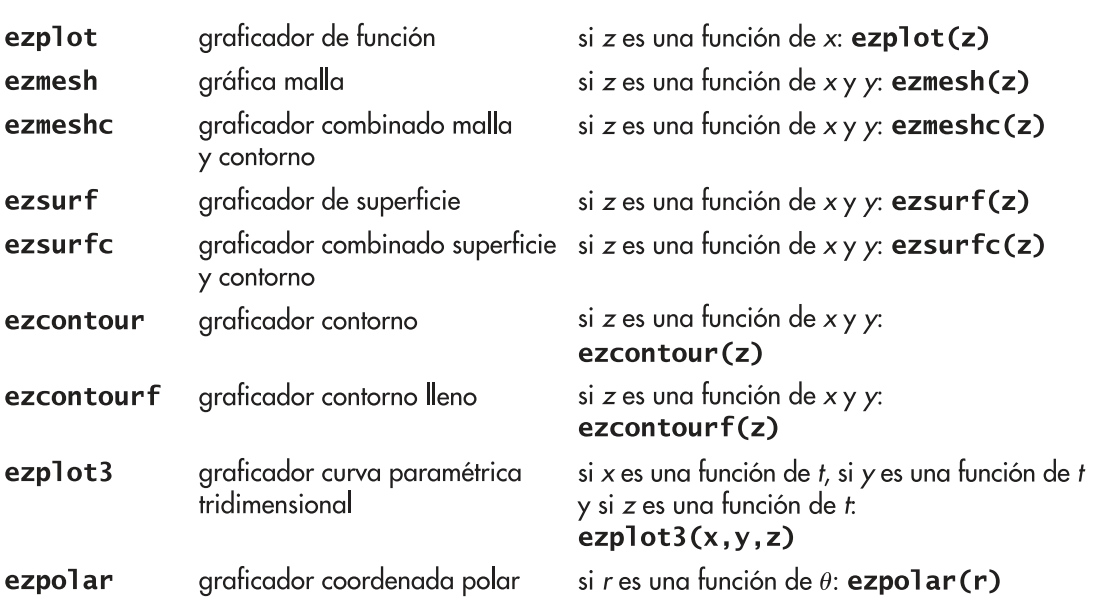

Para demostrar cómo trabajan las funciones de graficación de superficie tridimensional primero se define una versión simbólica de la función `peaks`.

clear

syms x y
z1 = 3*(1-x)^2*exp(-(x^2) - (y+1)^2);
z2 = -10*(x/5 - x^3 - y^5)*exp(-x^2-y^2);
z3 = -1/3*exp(-(x+1)^2 - y^2);
z = z1 + z2 + z3

Note que esta función se descompone en tres partes para hacerla más fácil de ingresar en la computadora.

subplot(2,2,1)
ezmesh(z)
    title 'ezmesh'

subplot(2,2,2)
ezmeshc(z)
    title 'ezmeshc'

subplot(2,2,3)
ezsurf(z)
    title 'ezsurf'

subplot(2,2,4)
ezsurfc(z)
    title 'ezsurfc'

subplot(2,2,1)
ezcontour(z)
    title 'ezcontour'

subplot(2,2,2)
ezcontourf(z)
    title 'ezcontourf'

subplot(2,2,3)
ezpolar(sin(x))
    title 'ezpolar'

subplot(2,2,4)
ezplot(sin(x))
    title 'ezplot'

**Nota:** Se recomienda realizar las mismas gráficas hechas hasta aquí pero con las funciones `f`.

## Documentación de las gráficas de funciones simbólicas

En el siguiente enlace se puede consultar toda la información acerca de la graficación de funciones simbólicas, amén de toda la información del álgebra simbólica de la cual se dispone en MATLAB: [Symbolic Math Toolbox](https://www.mathworks.com/help/releases/R2021b/symbolic/index.html?s_tid=CRUX_lftnav).